# Exercise 3

Will be plotting like the bike is 1 meter long.

**Sinewave**

[t, X] = ode45(@odefun_sine,[0 40],[0 0]);
x = -X(:,1);
v = -X(:,2); 
omega = 1/10*2*pi;
h0 = 0.5; % amplitude [m]
h = sin(omega.*t)*h0;

grid on
plot(t,x+h+1,t,h)
title('x position as when ground is a sine shape')
legend('Biker','Ground')
xlabel('time [s]')
ylabel('x [m]')
grid on

**Step**

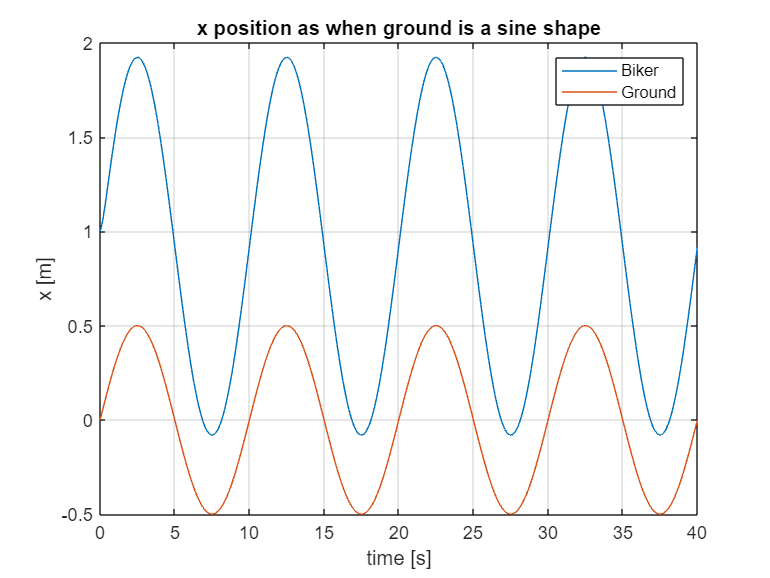


[t, X] = ode45(@odefun_step,[0 40],[0 0]);
x = -X(:,1);
v = -X(:,2); 

h0 = 0.5;
h = h0 - h0/2*heaviside(t-10)-h0/2*heaviside(t-20);

grid on

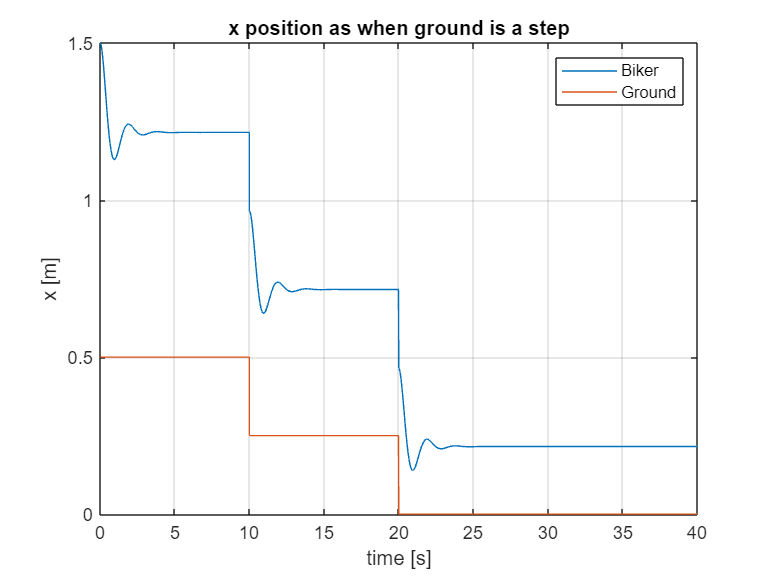

plot(t,x+h+1,t,h)
title('x position as when ground is a step')
legend('Biker','Ground')
xlabel('time [s]')
ylabel('x [m]')
grid on

**Odefun functions**

Sinewave:

function dydt = odefun_sine(t, y)
    % Extract variables from the y vector
    x = y(1);
    v = y(2);
    
    omega = 1/10*2*pi;
    h0 = 0.5; % amplitude [m]

    h = sin(omega*t)*h0;
    hdot = omega*cos(omega*t)*h0;

    m = 80;
    R = 2000;
    k = 10000;
    g = 9.81;

    % Define the system of ODEs
    xdot = v;
    vdot = g-k/m*(h+x)-R/m*(hdot+xdot);

    % Pack the derivatives into a column vector
    dydt = [xdot; vdot];
end


Step:

function dydt = odefun_step(t, y)
    % Extract variables from the y vector
    x = y(1);
    v = y(2);

    h0 = 0.5;
    h = h0 - h0/2*heaviside(t-10)-h0/2*heaviside(t-20);
    if t == 10 
        hdot = 1000;
    end
    if t == 20
        hdot = 1000;
    else
        hdot = 0;
    end

    m = 80;
    R = 200;
    k = 1000;
    g = 9.81;

    % Define the system of ODEs
    xdot = v;
    vdot = g-k/m*(h+x)-R/m*(hdot+xdot);

    % Pack the derivatives into a column vector
    dydt = [xdot; vdot];
end
